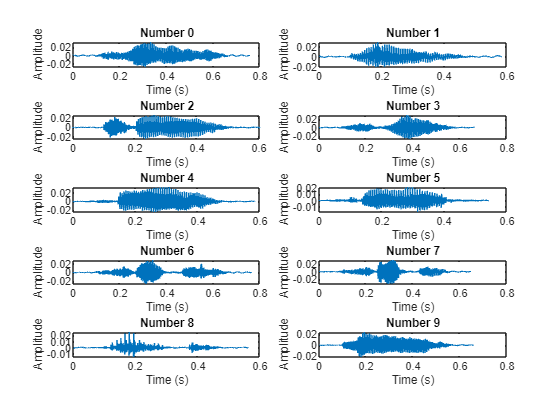

%Exercícios 1 e 2

energyThreshold = 0.003; %Definição do valor de energia mínimo considerada como silencio
figure;
for i = 0:9 
% Lê o primeiro audio de cada digito
    [audioData, samplingRate] = audioread(sprintf("Audios/%d_40_%d.wav", i, 0));
    % Cria o vetor de tempo
    time = (0:length(audioData)-1) / samplingRate; 

% Plot dos dados de audio
    subplot(5, 2, i+1);
    plot(time, audioData);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Number %d', i));
end

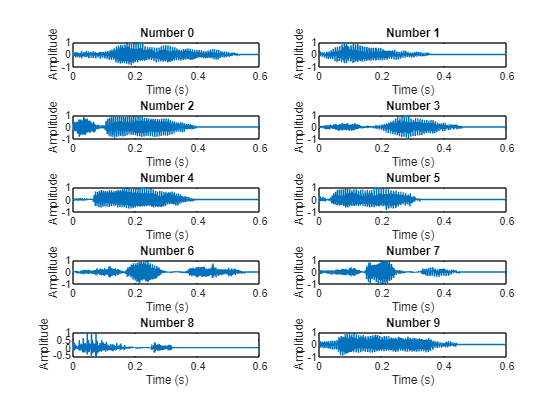


  
figure;    
for i = 0:9 
% Lê o primeiro audio de cada digito
    [audioData, samplingRate] = audioread(sprintf("Audios/%d_40_%d.wav", i, 0));

    audioData = removeSilence(audioData,energyThreshold); %Funcão que remove o silencio no principio e fim de cada sinal
    audioData = normalizeSignal(audioData); %Normalização do sinal de acordo com a amplitude maxima
    audioData = fillSilence(audioData, 0.6, samplingRate); %Adicionar silencio ao sinal para ter uma dada duração

% Cria o vetor de tempo
    time = (0:length(audioData)-1) / samplingRate; 

% Plot dos dados de audio
    subplot(5, 2, i+1);
    plot(time, audioData);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Number %d', i));
end

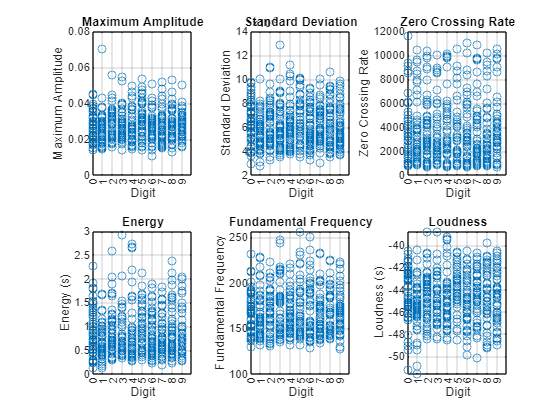



%Exercícios 3 e 4
%incializar os arrays para as features (cada linha de 50 valores
%corresponde a um digito)
maxAmplitudes = zeros(10, 50);
standardDeviation = zeros(10, 50);
zeroCrossingRates = zeros(10, 50);
energy = zeros(10,50);
fundFreq = zeros(10,50);
loudness = zeros(10,50);


%Loop pelos ficheiros de audio todos
for digit = 0:9
    for i = 0:49
        % Lê o ficheiro de audio
        [audioData, samplingRate] = audioread(sprintf("Audios/%d_40_%d.wav", digit, i));

        trimmedAudioData = removeSilence(audioData,energyThreshold);

        % Calculo das features
        maxAmplitudes(digit+1,i+1) = max(abs(trimmedAudioData)); %Cálculo da amplitude máxima
        standardDeviation(digit+1, i+1) = std(trimmedAudioData); %Calculo do desvio padrão
        energy(digit+1, i+1) = sum(trimmedAudioData.^2); % Calculo da energia(Dominio discreto)
        zeroCrossingRates(digit+1, i+1) = sum(abs(diff(sign(trimmedAudioData)))) / (2 * length(trimmedAudioData) / samplingRate);
        fundFreq(digit+1,i+1) = mean(pitch(trimmedAudioData, samplingRate)); % Média do pitch de cada frame
        loudness(digit+1,i+1) = integratedLoudness(audioData,samplingRate); %nao usa o audio trimmed
     end
end

matrix = repmat(0:9, 50, 1); %criação matriz
% Plot das features
figure;

% Amp max
subplot(2, 3, 1);
plot(reshape(matrix, [], 1), maxAmplitudes(:), 'o');
xlabel('Digit');
ylabel('Maximum Amplitude');
title('Maximum Amplitude');
set(gca, 'XTick', 0:9); 
grid on;

% Std
subplot(2, 3, 2);
plot(reshape(matrix, [], 1), standardDeviation(:), 'o');
xlabel('Digit');
ylabel('Standard Deviation');
title('Standard Deviation');
set(gca, 'XTick', 0:9); 
grid on;

% ZCR
subplot(2, 3, 3);
plot(reshape(matrix, [], 1), zeroCrossingRates(:), 'o');
xlabel('Digit');
ylabel('Zero Crossing Rate');
title('Zero Crossing Rate');
set(gca, 'XTick', 0:9); 
grid on;

% Energy
subplot(2, 3, 4);
plot(reshape(matrix, [], 1), energy(:), 'o');
xlabel('Digit');
ylabel('Energy (s)');
title('Energy');
set(gca, 'XTick', 0:9); 
grid on;

% Fundamental Frequency
subplot(2, 3, 5);
plot(reshape(matrix, [], 1), fundFreq(:), 'o');
xlabel('Digit');
ylabel('Fundamental Frequency');
title('Fundamental Frequency');
set(gca, 'XTick', 0:9); 
grid on;


% Loudness / Intensidade
subplot(2, 3, 6);
plot(reshape(matrix, [], 1), loudness(:), 'o');
xlabel('Digit');
ylabel('Loudness (s)');
title('Loudness');
set(gca, 'XTick', 0:9); 
grid on;

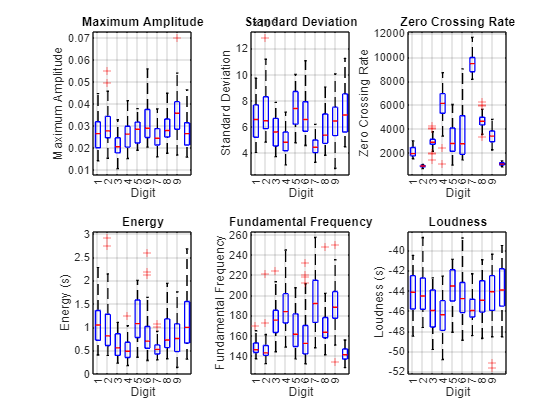


% Boxplot das features
figure;

% Amp max
subplot(2, 3, 1);
boxplot(maxAmplitudes', 'Labels', arrayfun(@num2str, 0:9, 'UniformOutput', false));
xlabel('Digit');
ylabel('Maximum Amplitude');
title('Maximum Amplitude');
set(gca, 'XTick', 0:9); 
grid on;

% Std
subplot(2, 3, 2);
boxplot(standardDeviation', 'Labels', arrayfun(@num2str, 0:9, 'UniformOutput', false));
xlabel('Digit');
ylabel('Standard Deviation');
title('Standard Deviation');
set(gca, 'XTick', 0:9); 
grid on;

% ZCR
subplot(2, 3, 3);
boxplot(zeroCrossingRates', 'Labels', arrayfun(@num2str, 0:9, 'UniformOutput', false));
xlabel('Digit');
ylabel('Zero Crossing Rate');
title('Zero Crossing Rate');
set(gca, 'XTick', 0:9); 
grid on;

% Energy
subplot(2, 3, 4);
boxplot(energy', 'Labels', arrayfun(@num2str, 0:9, 'UniformOutput', false));
xlabel('Digit');
ylabel('Energy (s)');
title('Energy');
set(gca, 'XTick', 0:9); 
grid on;

% Fundamental Frequency
subplot(2, 3, 5);
boxplot(fundFreq', 'Labels', arrayfun(@num2str, 0:9, 'UniformOutput', false));
xlabel('Digit');
ylabel('Fundamental Frequency');
title('Fundamental Frequency');
set(gca, 'XTick', 0:9); 
grid on;


% Loudness / Intensidade
subplot(2, 3, 6);
boxplot(loudness', 'Labels', arrayfun(@num2str, 0:9, 'UniformOutput', false));
xlabel('Digit');
ylabel('Loudness (s)');
title('Loudness');
set(gca, 'XTick', 0:9); 
grid on;